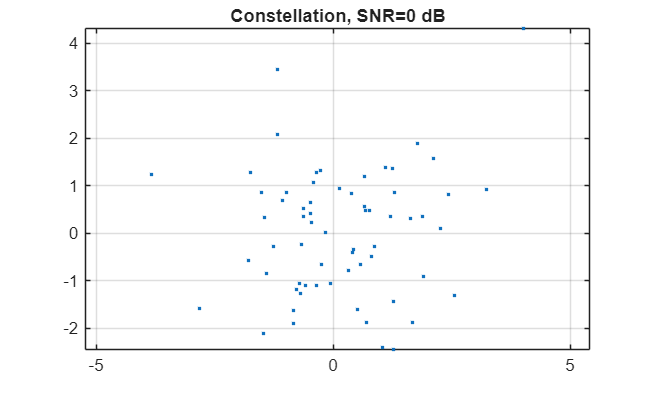

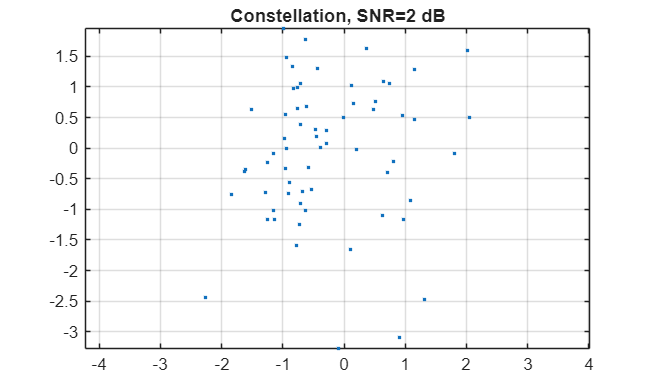

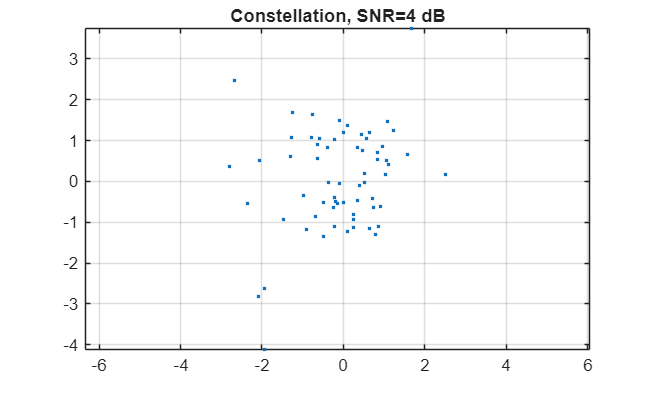

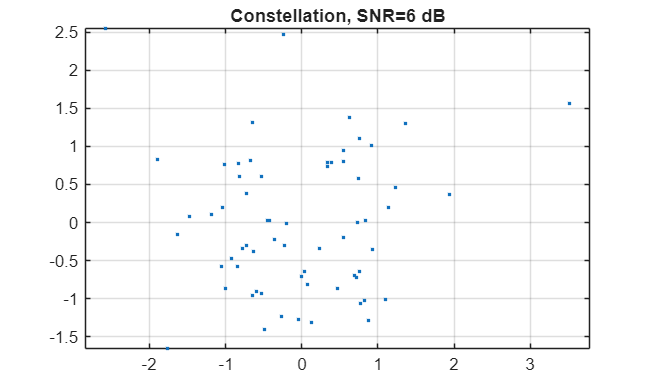

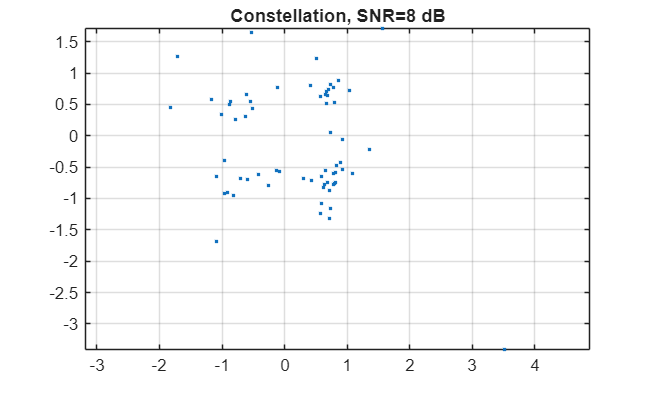

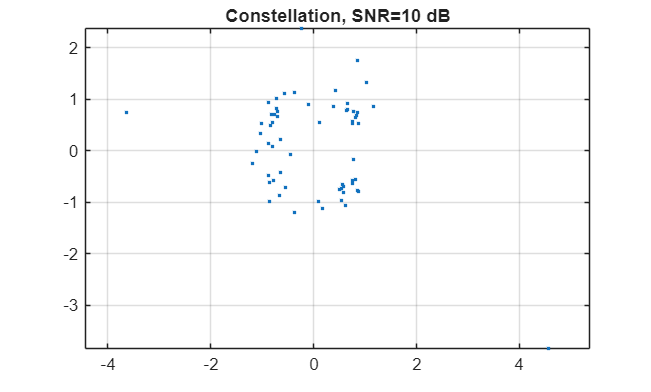

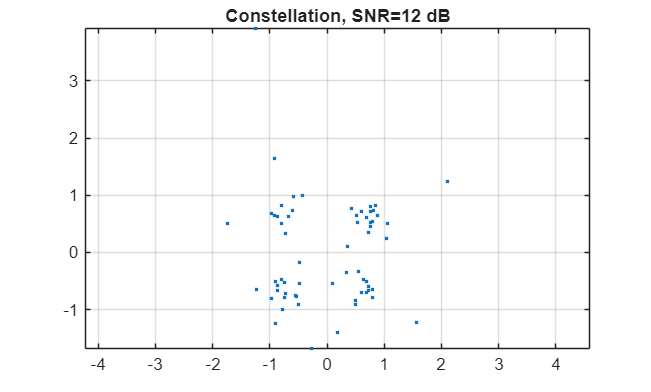

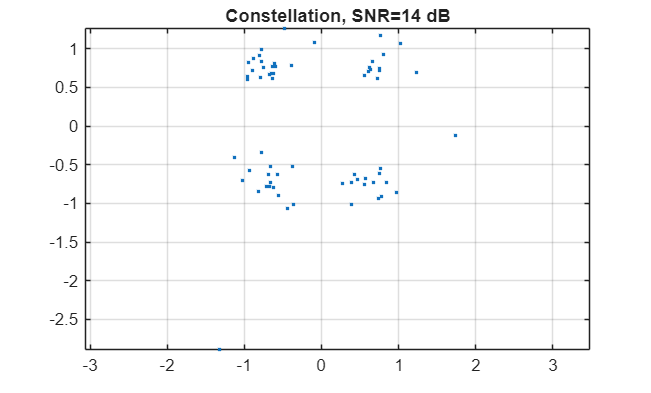

clear; clc; rng(1)

modSeviyesi = 4;                          % QPSK
bitSembol = log2(modSeviyesi);            % sembol başına bit sayısı
altTasiSayisi = 64;                       % N: alt taşıyıcı/sembol sayısı
herSNRicinSembolSayisi = 10000;             % ofdm sembol sayısı
SNRdB_listesi = 0:2:30;                   % dB cinsinden SNR değerleri

bitHataOrani = zeros(size(SNRdB_listesi));
sembolHataOrani = zeros(size(SNRdB_listesi));

for i = 1:numel(SNRdB_listesi)
    SNRdBdeger  = SNRdB_listesi(i);
    SNRlin      = 10^(SNRdBdeger/10);
    N0deger     = 1 / SNRlin;            

    bitHata = 0;   bitToplam = 0;
    sembolHata = 0; sembolToplam = 0;

    for tekrar = 1:herSNRicinSembolSayisi
        gidenBitler   = randi([0 1], altTasiSayisi*bitSembol, 1);
        gidenBitMat   = reshape(gidenBitler, bitSembol, []).';          
        gidenSembolInd = bi2de(gidenBitMat, 'left-msb');               

        gidenSemboller = qammod(gidenBitler, modSeviyesi, 'gray', ...
                                 'UnitAveragePower', true, 'InputType', 'bit');  

        %kanal  = (randn + 1j*randn) / sqrt(2);                           
        kanal = (randn(altTasiSayisi,1)+1j*randn(altTasiSayisi,1))/sqrt(2); % istersen frekans-seçici
        gurultu = sqrt(N0deger/2) * (randn(altTasiSayisi,1) + 1j*randn(altTasiSayisi,1)); % AWGN
        alinan  = kanal .* gidenSemboller + gurultu;

        % Eşitleme / csı perfect/kullanıcı kanalın genlık ve faz degisimini
        % biliyor
        tahminSemboller = alinan ./ kanal;

        gelenBitler     = qamdemod(tahminSemboller, modSeviyesi, 'gray', ...
                                   'UnitAveragePower', true, 'OutputType', 'bit');
        gelenSembolInd  = qamdemod(tahminSemboller, modSeviyesi, 'gray', ...
                                   'UnitAveragePower', true, 'OutputType', 'integer');

        bitHata    = bitHata    + sum(gelenBitler ~= gidenBitler);
        bitToplam  = bitToplam  + numel(gidenBitler);

        sembolHata   = sembolHata   + sum(gelenSembolInd ~= gidenSembolInd);
        sembolToplam = sembolToplam + numel(gidenSembolInd);
    end

    bitHataOrani(i)    = bitHata    / bitToplam;
    sembolHataOrani(i) = sembolHata / sembolToplam;

    figure; plot(real(tahminSemboller), imag(tahminSemboller), '.'); axis equal; grid on;
title(sprintf('Constellation, SNR=%d dB', SNRdBdeger));
end

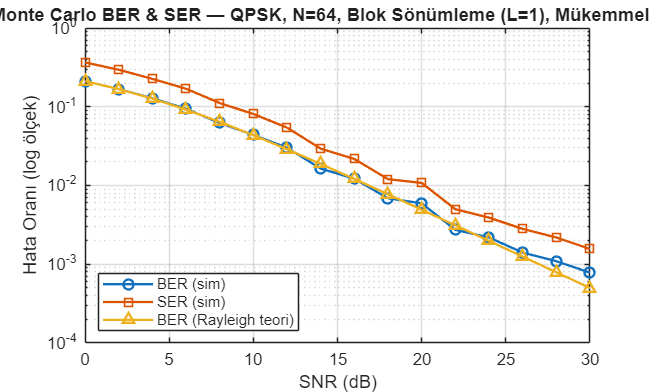


% Çizimler
figure;
semilogy(SNRdB_listesi, bitHataOrani, 'o-', 'LineWidth', 1.4); hold on; grid on;
semilogy(SNRdB_listesi, sembolHataOrani, 's-', 'LineWidth', 1.4);
xlabel('SNR (dB)'); ylabel('Hata Oranı (log ölçek)');
title(sprintf('Monte Carlo BER & SER — QPSK, N=%d, Blok Sönümleme (L=1), Mükemmel CSI', altTasiSayisi));
legend('BER', 'SER', 'Location', 'southwest');


EbN0lin = 10.^(SNRdB_listesi/10)/bitSembol;
BER_theory = 0.5*(1 - sqrt(EbN0lin./(1+EbN0lin)));
semilogy(SNRdB_listesi, BER_theory, '^-', 'LineWidth', 1.4);
legend('BER (sim)', 'SER (sim)', 'BER (Rayleigh teori)', 'Location','southwest');

%GRAFİK YORUMLARI 
%SER, grafiğe göre BER den daha yüksektir. bunun sebebi gary kodlama 
